clear all;
clf reset;

Read in CSV

data = readtable("bananas.csv")

data = 12531×4 table
            Origin               Date       Price     Units  
    ______________________    __________    _____    ________

    {'costa_rica'        }    2022-11-11       1     {'｣/kg'}
    {'guatemala'         }    2022-11-11    0.91     {'｣/kg'}
    {'dollar_bananas'    }    2022-11-11    0.96     {'｣/kg'}
    {'all_bananas'       }    2022-11-11    0.96     {'｣/kg'}
    {'colombia'          }    2022-11-04    0.97     {'｣/kg'}
    {'costa_rica'        }    2022-11-04       1     {'｣/kg'}
    {'dominican_republic'}    2022-11-04     0.9     {'｣/kg'}
    {'acp_bananas'       }    2022-11-04     0.9     {'｣/kg'}
    {'dollar_bananas'    }    2022-11-04       1     {'｣/kg'}
    {'all_bananas'       }    2022-11-04    0.99     {'｣/kg'}
    {'belize'            }    2022-10-28    0.95     {'｣/kg'}
    {'colombia'          }    2022-10-28    0.95     {'｣/kg'}
    {'costa_rica'        }    2022-10-28    0.98     {'｣/kg'}
    {'guatemala'         }    2022-10-28    0.91

Filter out unique origin and units

ori = unique(data.Origin);
units = unique(data.Units);

disp("Distinct " + length(ori) + " Origins:")

Distinct 28 Origins:


disp(ori)

    {'acp_bananas'       }
    {'all_bananas'       }
    {'belize'            }
    {'brazil'            }
    {'cameroon'          }
    {'colombia'          }
    {'costa_rica'        }
    {'dollar_bananas'    }
    {'dominican_republic'}
    {'ecuador'           }
    {'eu'                }
    {'eu_bananas'        }
    {'ghana'             }
    {'guadeloupe'        }
    {'guatemala'         }
    {'honduras'          }
    {'ivory_coast'       }
    {'jamaica'           }
    {'malaysia'          }
    {'martinique'        }
    {'mexico'            }
    {'nicaragua'         }
    {'panama'            }
    {'somalia'           }
    {'st_vincent'        }
    {'surinam'           }
    {'venezuela'         }
    {'windward_isles'    }



disp("Distinct " + length(units) + " Units:")

Distinct 1 Units:


disp(units)

    {'｣/kg'}



Hence there are 28 distinct origins and only 1 unit.

2. Mean prices. Aggregation group by Origin

aggr = grpstats(data, "Origin", "mean", "DataVars", "Price")

aggr = 28×3 table
                                  Origin            GroupCount    mean_Price
                          ______________________    __________    __________

    costa_rica            {'costa_rica'        }       1144        0.74284  
    guatemala             {'guatemala'         }        360        0.66719  
    dollar_bananas        {'dollar_bananas'    }       1249        0.68709  
    all_bananas           {'all_bananas'       }        646        0.73941  
    colombia              {'colombia'          }       1085        0.73633  
    dominican_republic    {'dominican_republic'}        763        0.63701  
    acp_bananas           {'acp_bananas'       }       1171        0.62421  
    belize                {'belize'            }        386        0.70425  
    panama                {'panama'            }        651        0.76091  
    ivory_coast           {'ivory_coast'       }        406        0.64778  
    cameroon              {'cameroon'          }        6

3. Box Plot

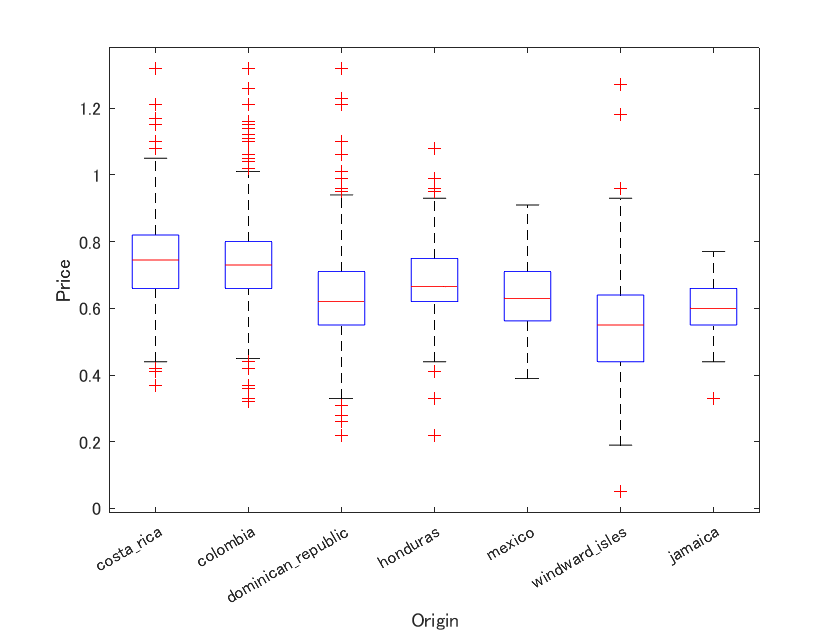

keys = { 'colombia', ...
    'costa_rica', ...
    'dominican_republic', ...
    'honduras',...
    'jamaica',...
    'windward_isles',...
    'mexico'
};
values = 1 : length(keys); 
map_index = containers.Map(keys, values);

prices = [];
origins = [];
all_origins = [];

for i = 1 : length(data.Origin) % for each row of the table
    this_origin = data.Origin(i); 
    this_origin = this_origin{1};
    all_origins = [all_origins; convertCharsToStrings(this_origin)];
    if ~isKey(map_index, this_origin) % not in keys
        continue;
    end
    prices = [prices; data.Price(i)]; % collect prices and origins
    origins = [origins; convertCharsToStrings(this_origin)];
end

figure;
boxplot(prices, origins);
xlabel("Origin")
ylabel("Price")

4. Time Series of Colombia

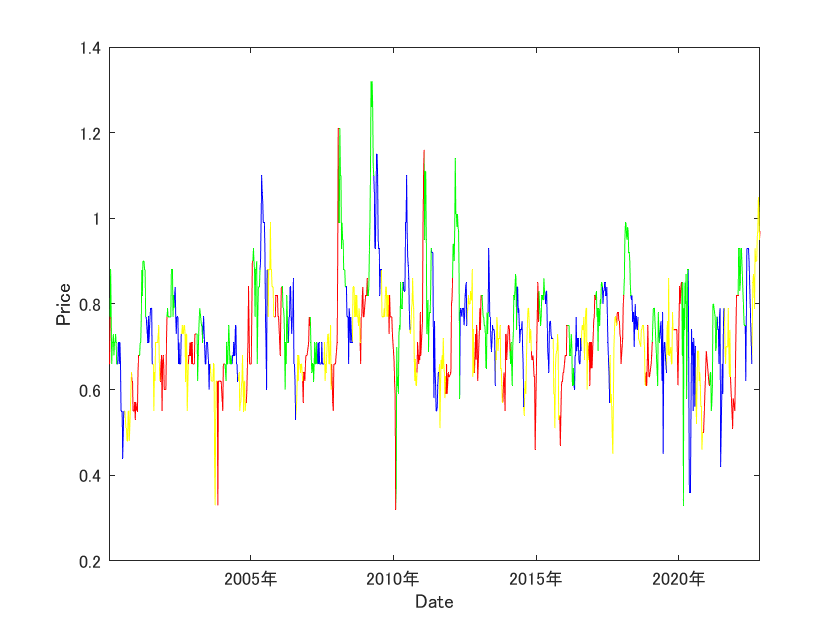

colombia_indexes = all_origins == 'colombia';

dates = data.Date(colombia_indexes);
pris = data.Price(colombia_indexes);

fig = figure;
for i = 1 : length(dates) - 1
    m = month(dates(i));
    if m < 2 || m > 10
        color = 'red';
    elseif m < 5
        color = 'green';
    elseif m < 8
        color = 'blue';
    else
        color = 'yellow';
    end
    plot(dates(i:i+1), pris(i:i+1), "Color", color);
    if i == 1
        hold on 
    end
end
xlabel("Date")
ylabel("Price")
hold off

5. Correlation Coefficients of Colombia and Costa Rica 

costa_rica_indexes = all_origins == 'costa_rica';

dates2 = data.Date(costa_rica_indexes);
pris2 = data.Price(costa_rica_indexes);

uni_times = max(min(datenum(dates2)), min(datenum(dates))) ...
    : min(max(datenum(dates2)), max(datenum(dates)));
uni_times = datetime(uni_times, "ConvertFrom", "datenum");

pris_ = interp1(dates, pris, uni_times, "linear")';
pris2_ = interp1(dates2, pris2, uni_times, "linear")';

disp("Correlation Coefficients:")

Correlation Coefficients:


corrcoef([pris_ pris2_])

ans =     1.0000    0.7695
    0.7695    1.0000
